## Optimize IPTG concentration for FA3 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','1') % FA3 model

p = sdo.getParameterFromModel(modelName,'IPTG');

p.Value = 100;
p.Minimum = 0;
p.Maximum = 1000;
p.Scale = 1000;
p.Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -2.0121

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 10-Nov-2023 22:28:31

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      3     -2.01205            0
    1     17     -2.01253            0       0.0149        0.512
    2     20      -2.0145            0      0.00602       0.0923
    3     23     -2.01458            0      0.00133       0.0157
    4     26     -2.01458            0     0.000193     0.000597
制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。
 
optInput =
 
       Name: 'IPTG'
      Value: 107.7166
    Minimum: 0
    Maximum: 1000
       Free: 1
      Scale: 1000
       Info: [1×1 struct]

 
1x1 param.Continuous
 
lists of methods, superclasses
 


optInputInfo = フィールドをもつ struct :
               F: -2.0146
       Gradients: [1×1 struct]
        exitflag: 1
      iterations: 4
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 19.548258 秒です。


maxFFA_FA3 = -optInputInfo.SolverOutput.fval;

save('optInput_FA3','optInput')
sdo.setValueInModel(modelName,optInput);

## Plot the convex curve

setPointValues = logspace(0,3,100); % 1-1000 uM IPTG
spv_length = length(setPointValues);
for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(setPointValues(i)));
end

out_FA3 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[10-Nov-2023 22:29:41] シミュレーションの実行中...
[10-Nov-2023 22:29:42] シミュレーション実行 1/100 が完了
[10-Nov-2023 22:29:42] シミュレーション実行 2/100 が完了
[10-Nov-2023 22:29:43] シミュレーション実行 3/100 が完了
[10-Nov-2023 22:29:44] シミュレーション実行 4/100 が完了
[10-Nov-2023 22:29:45] シミュレーション実行 5/100 が完了
[10-Nov-2023 22:29:45] シミュレーション実行 6/100 が完了
[10-Nov-2023 22:29:46] シミュレーション実行 7/100 が完了
[10-Nov-2023 22:29:47] シミュレーション実行 8/100 が完了
[10-Nov-2023 22:29:47] シミュレーション実行 9/100 が完了
[10-Nov-2023 22:29:48] シミュレーション実行 10/100 が完了
[10-Nov-2023 22:29:49] シミュレーション実行 11/100 が完了
[10-Nov-2023 22:29:49] シミュレーション実行 12/100 が完了
[10-Nov-2023 22:29:50] シミュレーション実行 13/100 が完了
[10-Nov-2023 22:29:51] シミュレーション実行 14/100 が完了
[10-Nov-2023 22:29:51] シミュレーション実行 15/100 が完了
[10-Nov-2023 22:29:52] シミュレーション実行 16/100 が完了
[10-Nov-2023 22:29:53] シミュレーション実行 17/100 が完了
[10-Nov-2023 22:29:54] シミュレーション実行 18/100 が完了
[10-Nov-2023 22:29:54] シミュレーション実行 19/100 が完了
[10-Nov-2023 22:29:55] シミュレーション実行 20/100 が完了
[10-Nov-2023 22:29:56] シミュレーション実行 21/100 が完了
[10-Nov-2023 22:29:56] シミ

out_FA3 = 1x100 Simulink.SimulationOutput 配列



FFA_end_FA3 = zeros(spv_length,2);
FFA_end_FA3(:,1) = setPointValues;
for i = 1:1:spv_length
    FFA_end_FA3(i,2) = out_FA3(i).logsout{1}.Values.Data(end);
end

FFAData = zeros(6,2);
FFAData(:,1) = [0 10 40 100 400 1000]';
load("FA3Data.mat")
for expIdx = 1:6
    FFAData(expIdx,2) = FA3Data(8,expIdx + 1,2);
end

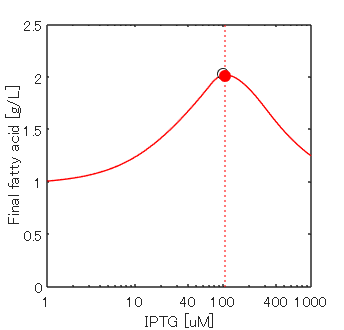

figure('Position', [120 120 250 240]);
plot(FFA_end_FA3(:,1),FFA_end_FA3(:,2),'r-')
xline(optInput.Value,'r:')
xlim([1 1000])
ylim([0 2.5])
xlabel('IPTG [uM]')
xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
hold on
plot(FFAData(:,1),FFAData(:,2),'ko','MarkerFaceColor','w')
plot(optInput.Value,maxFFA_FA3,'ro','MarkerFaceColor','r')
hold off
set(gca,'xscale','log')